%ModeShapeTipMassRitz.mlx

clc; clear;
syms bL
eqn = cos(bL)*cosh(bL) == -1;
bLi= [];
for i = 1:1:10
    j = i + 1;
    b1 = vpasolve(eqn, bL, [i j]);

    b1 = double(b1);
    bLi = [bLi, b1];
end
bLi

bLi =     1.8751    4.6941    7.8548   10.9955



L = 1; % Length of the Beam (m)
b = 50e-3; % Width of the Beam (m)
d = 10e-3; % Depth of the Beam (m)
E = 20.5e10; % Modulus of Elasticity of the Beam Material (N/m^2)
rho = 7.8e3; % Density of the Beam Material (kg/m^3)
m_tip = 0.5; % Point mass at the tip of the beam (kg)

A = b * d; % Area of Cross-Section of the Beam
I = b * d^3 / 12; % Second Moment of Area of Beam
m_beam = rho * A * L; % Mass of the Beam

% Rayleigh-Ritz approximation for natural frequency
wn = (bLi).^2 * sqrt((E * I) / (rho * A * L^4));
wn_adj = wn .* sqrt(1 ./ (1 + (m_tip / (m_beam / 420)) * (bLi / L).^2));
fn = wn_adj / (2 * pi);
fn

fn =     0.6003    1.5061    2.5209    3.5291


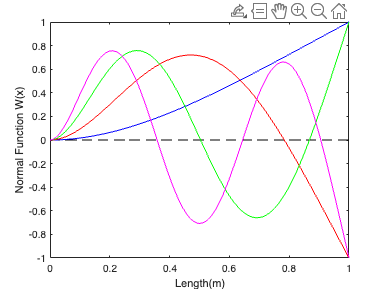


% Base State
dx = 0.01;
x = 0:dx:L;
W0 = zeros(1, length(x));
plot(x, W0, 'k--')
hold on
xlabel('Length(m)');
ylabel('Normal Function W(x)');

% First Mode
bL = bLi(1);
W1 = ModeShape(bL, dx, L);
plot(x, W1, 'b')
hold on
% Second Mode
bL = bLi(2);
W2 = ModeShape(bL, dx, L);
plot(x, W2, 'r')
hold on
% Third Mode
bL = bLi(3);
W3 = ModeShape(bL, dx, L);
plot(x, W3, 'g')
% 4th Mode
bL = bLi(4);
W4 = ModeShape(bL, dx, L);
plot(x, W4, 'm')

function W = ModeShape(bL, dx, L)
    b = bL / L;
    C = cos(bL); S = sin(bL); Ch = cosh(bL); Sh = sinh(bL);
    a = (S + Sh) / (C + Ch);
    x = 0:dx:L;
    C = cos(b * x); S = sin(b * x); Ch = cosh(b * x); Sh = sinh(b * x);
    W = (S - Sh) - a * (C - Ch);
    W = W / max(abs(W)); % Normalize the mode shape for visualization
end
